# Runs a program in blocks

%Initial
v0 = 5; theta = 45; g = 9.81;
t = 0:0.1:1;
x = v0*cosd(theta)*t;
y = v0*sin(theta)*t-g*t.^2/2;
Table = [t;x;y];
% Write to file
file = fopen('工程計算與設計/Ch1/dat/Datafile01_11.dat','w+');
fprintf(file, '\n Time (s)   Distance (m)   Height (m)\n');
fprintf(file, '%8.1f %13.4f %13.4f\n',Table);
fclose(file);
% Read from file
file = fopen('工程計算與設計/Ch1/dat/Datafile01_11.dat','r+');
fscanf(file, '\n Time (s)   Distance (m)   Height (m)\n');
Table = fscanf(file,'%f %f %f\n',[3,11]); % [rows,cols]
fclose(file);
% Print on screen
fprintf('\n Time (s)   Distance (m)   Height (m)\n');


 Time (s)   Distance (m)   Height (m)


fprintf('%8.1f %13.4f %13.4f\n',Table);

     0.0        0.0000        0.0000
     0.1        0.3536        0.3764
     0.2        0.7071        0.6547
     0.3        1.0607        0.8349
     0.4        1.4142        0.9170
     0.5        1.7678        0.9010
     0.6        2.1213        0.7869
     0.7        2.4749        0.5747
     0.8        2.8284        0.2644
     0.9        3.1820       -0.1440
     1.0        3.5355       -0.6505


## Creates a trajectory table, saves all the variables to a MAT file, loads the variables from the MAT file, and prints the table on the screen.

v0 = 5; theta = 45; g = 9.81;
t = 0:0.1:1;
x = v0*cosd(theta)*t;
y = v0*sin(theta)*t-g*t.^2/2;
Table = [t;x;y];
% Write to file
save('工程計算與設計/Ch1/dat/Datafile01_12');
% Read from file
clear
load('工程計算與設計/Ch1/dat/Datafile01_12');
% Print on screen
fprintf('\n Time (s)   x (m)   y (m)\n');


 Time (s)   x (m)   y (m)


fprintf('%10.1f %9.3f %9.3f\n',Table);

       0.0     0.000     0.000
       0.1     0.354     0.376
       0.2     0.707     0.655
       0.3     1.061     0.835
       0.4     1.414     0.917
       0.5     1.768     0.901
       0.6     2.121     0.787
       0.7     2.475     0.575
       0.8     2.828     0.264
       0.9     3.182    -0.144
       1.0     3.536    -0.650


## Reads an image file, displays the image on the screen, loads a sound file, plays the sound, and plots the sound audio signals.

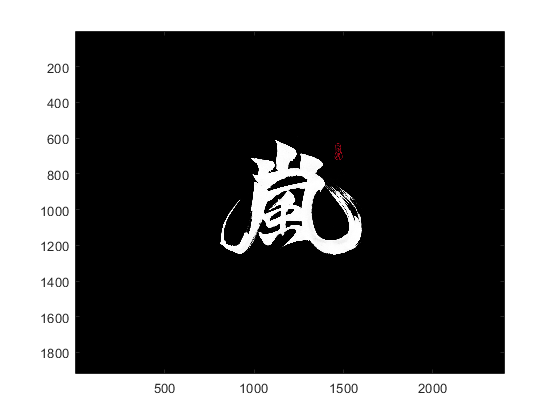

photo = imread('工程計算與設計/Ch1/dat/text.png');
image(photo)
axis image

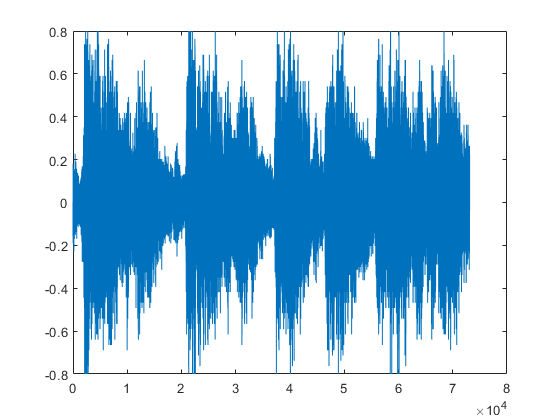

load handel %聲音訊號y 和取樣頻率Fs 都事先儲存在handel.mat 檔案中
% sound(y,Fs); % 播放此音訊
plot(y)

## Creates a trajectory table and prints the table using a for-loop.

v0 = 5; theta = 45; g = 9.81;
fprintf('\n Time (s)   x (m)   y (m)\n');


 Time (s)   x (m)   y (m)


for t = 0:0.1:1
    x = v0*cosd(theta)*t;
    y = v0*sind(theta)*t-g*t.^2/2;
    fprintf('%10.1f %9.3f %9.3f\n',t,x,y);
end

       0.0     0.000     0.000
       0.1     0.354     0.305
       0.2     0.707     0.511
       0.3     1.061     0.619
       0.4     1.414     0.629
       0.5     1.768     0.542
       0.6     2.121     0.356
       0.7     2.475     0.071
       0.8     2.828    -0.311
       0.9     3.182    -0.791
       1.0     3.536    -1.369


## Creates a trajectory table and prints the table, using user-defined functions.

global g
v0 = 5;theta=45; g=9.81;
t = 0:0.1:1;
[distance,height] = generateTable(v0,theta,t);
printTable(t,distance,height)

Time (s)   x(m)    y (m)
       0.0     0.000     0.000
       0.1     0.354     0.305
       0.2     0.707     0.511
       0.3     1.061     0.619
       0.4     1.414     0.629
       0.5     1.768     0.542
       0.6     2.121     0.356
       0.7     2.475     0.071
       0.8     2.828    -0.311
       0.9     3.182    -0.791
       1.0     3.536    -1.369


ans =          0    0.3536    0.7071    1.0607    1.4142    1.7678    2.1213    2.4749    2.8284    3.1820    3.5355


## Creates a trajectory table and prints the table using cell arrays.

v0 = 5; theta = 45; g = 9.81;
t = 0:0.1:1;
x = v0* cosd(theta)*t;
y = v0*sind(theta)*t-g*t.^2/2;
Trajectory = {v0,theta,t,x,y};
printTrajectory1(Trajectory)

Initial velocity = 5 m/s
Elevation angle = 45 degrees

Time (s)   x(m)    y (m)
       0.0     0.000     0.000
       0.1     0.354     0.305
       0.2     0.707     0.511
       0.3     1.061     0.619
       0.4     1.414     0.629
       0.5     1.768     0.542
       0.6     2.121     0.356
       0.7     2.475     0.071
       0.8     2.828    -0.311
       0.9     3.182    -0.791
       1.0     3.536    -1.369


## Creates a trajectory table and prints the table using structure data.

v0 = 5; theta = 45; g = 9.81;
t = 0:0.1:1;
x = v0* cosd(theta)*t;
y = v0*sind(theta)*t-g*t.^2/2;
Trajectory={};
Trajectory.velocity = v0;
Trajectory.angle = theta;
Trajectory.time = t;
Trajectory.distance = x ;
Trajectory.height = y;
printTrajectory2(Trajectory)

Initial velocity = 5 m/s
Elevation angle = 45 degrees

 Time (s)  x(m)    y (m)
       0.0     0.000     0.000
       0.1     0.354     0.305
       0.2     0.707     0.511
       0.3     1.061     0.619
       0.4     1.414     0.629
       0.5     1.768     0.542
       0.6     2.121     0.356
       0.7     2.475     0.071
       0.8     2.828    -0.311
       0.9     3.182    -0.791
       1.0     3.536    -1.369



% function [輸出變數]=Name_of_function(輸入參數)
function [x,y] = generateTable(v0,angle,time)
    global g
    x = v0*cosd(angle)*time;
    y = v0*sind(angle)*time-g*time.^2/2;
end
function [x,y] = printTable(t,x,y)
fprintf('Time (s)   x(m)    y (m)\n');
    for k = 1:length(t)
        fprintf('%10.1f %9.3f %9.3f\n', t(k),x(k),y(k))
    end
end
function printTrajectory1 (Traj)
    fprintf('Initial velocity = %0.f m/s\n',Traj{1})
    fprintf('Elevation angle = %0.f degrees\n\n',Traj{2})
    fprintf('Time (s)   x(m)    y (m)\n')
    for k =1:length(Traj{3})
        fprintf('%10.1f %9.3f %9.3f\n', Traj{3}(k),Traj{4}(k),Traj{5}(k))
    end
end

function printTrajectory2 (Traj)
    fprintf('Initial velocity = %0.f m/s\n',Traj.velocity)
    fprintf('Elevation angle = %0.f degrees\n\n',Traj.angle)
    fprintf(' Time (s)  x(m)    y (m)\n');
    for k = 1:length(Traj.time)
        fprintf('%10.1f %9.3f %9.3f\n',Traj.time(k),Traj.distance(k),Traj.height(k))
    end    
end